# MAC_Seq2seq

## Create dlnetwork

lgraph = layerGraph();

## Add layer branchs

Add a branch to the dlnetwork. Each branch is a linear set of layers.

tempNet = [
    sequenceInputLayer(1,"Name","sequence","MinLength",300)
    convolution1dLayer(9,256,"Name","conv1d","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_1")
    dropoutLayer(0.1,"Name","dropout_1")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1_1","NumValueChannels",256,"OutputSize",256);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(3,"Name","addition_1")
    convolution1dLayer(7,128,"Name","conv1d_2","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_2")
    dropoutLayer(0.1,"Name","dropout_2")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1","NumValueChannels",256,"OutputSize",128);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(3,"Name","addition_2")
    convolution1dLayer(7,128,"Name","conv1d_2_4","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_2_1")
    dropoutLayer(0.1,"Name","dropout_2_1")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1_2","NumValueChannels",256,"OutputSize",128);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(3,"Name","addition_2_2")
    convolution1dLayer(7,128,"Name","conv1d_2_5","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_2_2")
    dropoutLayer(0.1,"Name","dropout_2_2")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1_3","NumValueChannels",256,"OutputSize",128);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(3,"Name","addition_1_1")
    convolution1dLayer(7,128,"Name","conv1d_2_6","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_2_3")
    dropoutLayer(0.1,"Name","dropout_2_3")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1_4","NumValueChannels",256,"OutputSize",128);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(3,"Name","addition_1_2")
    convolution1dLayer(7,128,"Name","conv1d_2_7","Padding","same","Stride",2)];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    reluLayer("Name","relu_2_4")
    dropoutLayer(0.1,"Name","dropout_2_4")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention_1_5","NumValueChannels",256,"OutputSize",128);
lgraph = addLayers(lgraph,tempNet);

tempNet = additionLayer(3,"Name","addition_1_3");
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution1dLayer(7,128,"Name","conv1d_2_1","Padding","same","Stride",2)
    batchNormalizationLayer("Name","batchnorm")
    reluLayer("Name","relu")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution1dLayer(5,128,"Name","conv1d_2_2","Padding","same","Stride",2)
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_4")];
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution1dLayer(3,128,"Name","conv1d_2_3","Padding","same","Stride",2)
    batchNormalizationLayer("Name","batchnorm_1")
    reluLayer("Name","relu_3")];
lgraph = addLayers(lgraph,tempNet);

tempNet = additionLayer(3,"Name","addition_2_1");
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    convolution1dLayer(3,32,"Name","conv1d_1","Padding","same")
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_5")
    dropoutLayer(0.1,"Name","dropout")];
lgraph = addLayers(lgraph,tempNet);

tempNet = selfAttentionLayer(4,256,"Name","selfattention","OutputSize",32);
lgraph = addLayers(lgraph,tempNet);

tempNet = [
    additionLayer(2,"Name","addition")
    flattenLayer("Name","flatten")
    indexing1dLayer("first","Name","indexing")
    fullyConnectedLayer(32,"Name","fc")
    fullyConnectedLayer(6,"Name","fc_1")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempNet);

% 清理辅助变量
clear tempNet;

##  Connection layer branch

Connect all branches of the network to create a network diagram.

lgraph = connectLayers(lgraph,"conv1d","relu_1");
lgraph = connectLayers(lgraph,"conv1d","selfattention_1_1");
lgraph = connectLayers(lgraph,"conv1d","addition_1/in3");
lgraph = connectLayers(lgraph,"dropout_1","addition_1/in1");
lgraph = connectLayers(lgraph,"selfattention_1_1","addition_1/in2");
lgraph = connectLayers(lgraph,"conv1d_2","relu_2");
lgraph = connectLayers(lgraph,"conv1d_2","selfattention_1");
lgraph = connectLayers(lgraph,"conv1d_2","addition_2/in2");
lgraph = connectLayers(lgraph,"dropout_2","addition_2/in1");
lgraph = connectLayers(lgraph,"selfattention_1","addition_2/in3");
lgraph = connectLayers(lgraph,"conv1d_2_4","relu_2_1");
lgraph = connectLayers(lgraph,"conv1d_2_4","selfattention_1_2");
lgraph = connectLayers(lgraph,"conv1d_2_4","addition_2_2/in3");
lgraph = connectLayers(lgraph,"dropout_2_1","addition_2_2/in1");
lgraph = connectLayers(lgraph,"selfattention_1_2","addition_2_2/in2");
lgraph = connectLayers(lgraph,"conv1d_2_5","relu_2_2");
lgraph = connectLayers(lgraph,"conv1d_2_5","selfattention_1_3");
lgraph = connectLayers(lgraph,"conv1d_2_5","addition_1_1/in3");
lgraph = connectLayers(lgraph,"dropout_2_2","addition_1_1/in1");
lgraph = connectLayers(lgraph,"selfattention_1_3","addition_1_1/in2");
lgraph = connectLayers(lgraph,"conv1d_2_6","relu_2_3");
lgraph = connectLayers(lgraph,"conv1d_2_6","selfattention_1_4");
lgraph = connectLayers(lgraph,"conv1d_2_6","addition_1_2/in3");
lgraph = connectLayers(lgraph,"dropout_2_3","addition_1_2/in1");
lgraph = connectLayers(lgraph,"selfattention_1_4","addition_1_2/in2");
lgraph = connectLayers(lgraph,"conv1d_2_7","relu_2_4");
lgraph = connectLayers(lgraph,"conv1d_2_7","selfattention_1_5");
lgraph = connectLayers(lgraph,"conv1d_2_7","addition_1_3/in3");
lgraph = connectLayers(lgraph,"dropout_2_4","addition_1_3/in1");
lgraph = connectLayers(lgraph,"selfattention_1_5","addition_1_3/in2");
lgraph = connectLayers(lgraph,"addition_1_3","conv1d_2_1");
lgraph = connectLayers(lgraph,"addition_1_3","conv1d_2_2");
lgraph = connectLayers(lgraph,"addition_1_3","conv1d_2_3");
lgraph = connectLayers(lgraph,"relu","addition_2_1/in1");
lgraph = connectLayers(lgraph,"relu_4","addition_2_1/in3");
lgraph = connectLayers(lgraph,"relu_3","addition_2_1/in2");
lgraph = connectLayers(lgraph,"addition_2_1","conv1d_1");
lgraph = connectLayers(lgraph,"addition_2_1","selfattention");
lgraph = connectLayers(lgraph,"dropout","addition/in1");
lgraph = connectLayers(lgraph,"selfattention","addition/in2");

## Plot lgraph

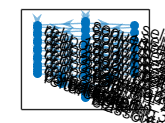

plot(lgraph);